# Simulación de prueba 

Se realiza una prueba con una planta cualquiera:


$$G\left(s\right)=\frac{0\ldotp 5}{s^2 +s+1}$$


G=tf([0.5],[1 1 1])


G =
 
      0.5
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



[A,B,C,D]=tf2ss(0.5,[1 1 1]); %Espacio de estados
Gss=ss(A,B,C,0);

Control por realimentacion de estados continuo:

K=place(A,B,[-1+j -1-j])

K =      1     1


Sistema a lazo cerrado en espacio de estados

tfinal=5;  %Tiempo final de simulacion 50 segundos
Gsf_ss=ss(A-B*K,B,C,0)


Gsf_ss =
 
  A = 
       x1  x2
   x1  -2  -2
   x2   1   0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
        x1   x2
   y1    0  0.5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



[yy,tt,xx]=step(Gsf_ss,tfinal);
plot(tt,yy,'LineWidth',3)
title('Respuesta el escalon unitario a lazo cerrado ideal')
grid on

Se define periodos de muestreo para el controlador por eventos y el tamaño del paso para la simulación

Tsp=.001; %tamaño del paso para la simulación
Ts=0.01;   %periodo de muestreo del controlador por eventos
D=c2d(Gss,Tsp) %discretizacion de la planta para simular


D =
 
  A = 
               x1          x2
   x1       0.999  -0.0009995
   x2   0.0009995           1
 
  B = 
              u1
   x1  0.0009995
   x2  4.998e-07
 
  C = 
        x1   x2
   y1    0  0.5
 
  D = 
       u1
   y1   0
 
Sample time: 0.001 seconds
Discrete-time state-space model.



Control por realimentacion de estados discreto:

p_discreto(1)=exp((-1+j)*Ts)

p_discreto =    0.9900 + 0.0099i   0.9900 - 0.0099i


p_discreto(2)=exp((-1-j)*Ts)

p_discreto =    0.9900 + 0.0099i   0.9900 - 0.0099i


incertidumbre_de_A=[0.3,-0.5;0.1,0.5];
incertidumbre_de_B=[0;0];
D_1=c2d(ss(A+incertidumbre_de_A,B+incertidumbre_de_B,C,0),Ts) %discretizacion de la planta para el algoritmo de control


D_1 =
 
  A = 
             x1        x2
   x1    0.9929  -0.01498
   x2   0.01099     1.005
 
  B = 
              u1
   x1   0.009965
   x2  5.496e-05
 
  C = 
        x1   x2
   y1    0  0.5
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.




Kd=place(D_1.A,D_1.B,[p_discreto(1) p_discreto(2)])

Kd =     1.7856    1.4317



D_cl=ss(D_1.A-D_1.B*Kd,D_1.B,D_1.C,0,Ts)


D_cl =
 
  A = 
             x1        x2
   x1    0.9751  -0.02925
   x2   0.01089     1.005
 
  B = 
              u1
   x1   0.009965
   x2  5.496e-05
 
  C = 
        x1   x2
   y1    0  0.5
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



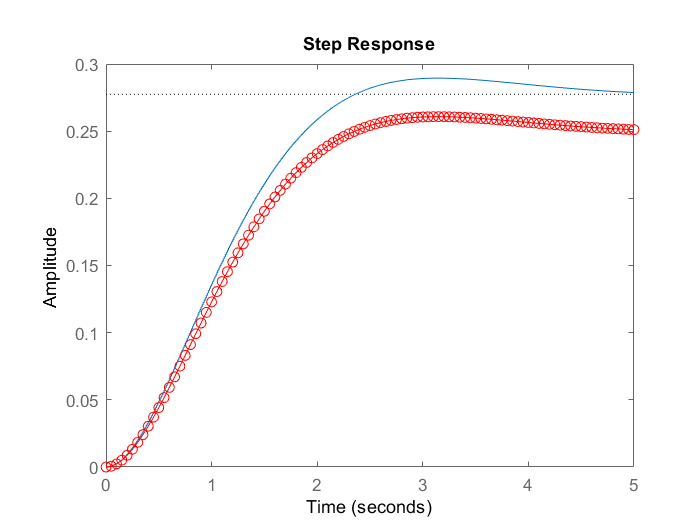

step(D_cl,tfinal)
hold on
plot(tt,yy,'-or')
hold off

No existen comandos para simular control por eventos en MATLAB, por eso se realiza la simulación con el siguiente script:

clear t u uc up ui y x e es elim hact hmax eventos
t=0:Tsp:tfinal;
u=0;uc=0

uc = 0

norma=zeros(0,length(t)-1);
eventos=zeros(0,length(t)-1);
e=zeros(0,length(t)-1);

%Condiciones iniciales
x=[0;1];
xs=[0;0];
y=Gss.C*x;

r=1;elim=.05;hmax=6; %referencia, umbral y umbral temporal

%A_tilde=(D_1.A+[0.01 0.05;0.01 0.05])-D_1.B*Kd;
A_tilde=(D_1.A)-D_1.B*Kd;
k=1;
for i=1:length(t)-1
    e(i)=0-y(i);

    eventos(i)=0;
    if(mod(t(i),Ts)==0)  %el controlador solo toma muestras con un periodo T=0.1
        xs(:,k+1)=A_tilde*xs(:,k);
        norma(i)=norm(x(:,i)-xs(:,k));
        if(norma(i)>=elim)
            xs(:,k)=x(:,i);
            xs(:,k+1)=A_tilde*xs(:,k);
            eventos(i)=1;
        end 

        uc=-Kd*xs(:,k);
        k=k+1;
    end
    
    u(i)=uc;
    x(:,i+1)=D.A*x(:,i)+D.B*u(i);
    y(i+1)=D.C*x(:,i+1);
end

Graficas de los resultados de la simulación

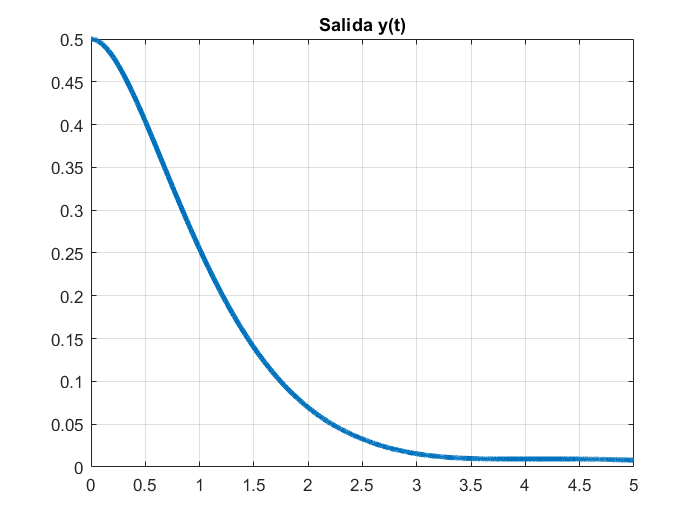

%[y,x,t,Kd,u,e,N,M,eventos]=state_approach_based(A,B,C,[-1+j -1-j],t,elim,incertidumbre_de_A,incertidumbre_de_B,Ts,[0;1],[0;0]);

plot(t,y,'LineWidth',3) %salida
grid on
title('Salida y(t)')

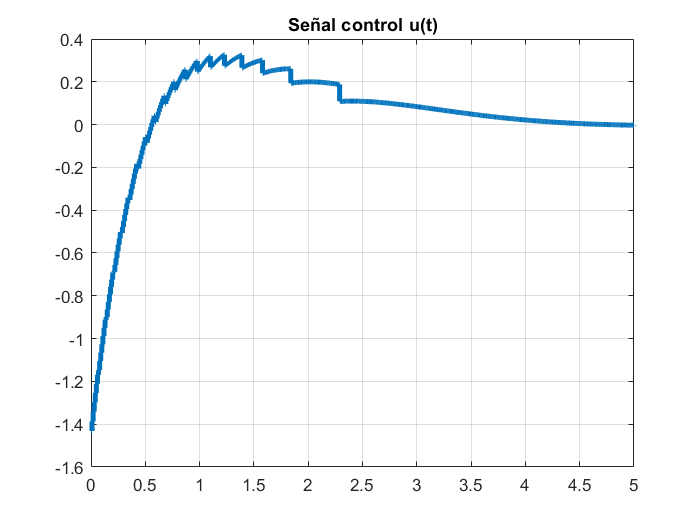

plot(t,[u 0],'LineWidth',3)%señal de control
grid on
title('Señal control u(t)')

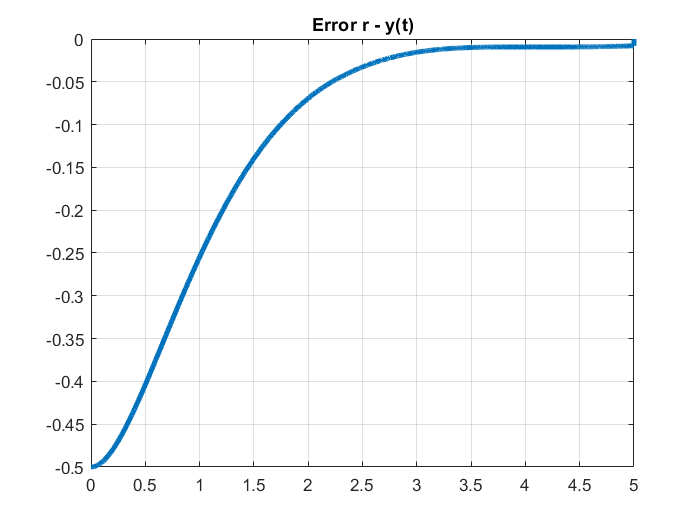

plot(t,[e 0],'LineWidth',3)%señal de error
grid on
title('Error r - y(t)')

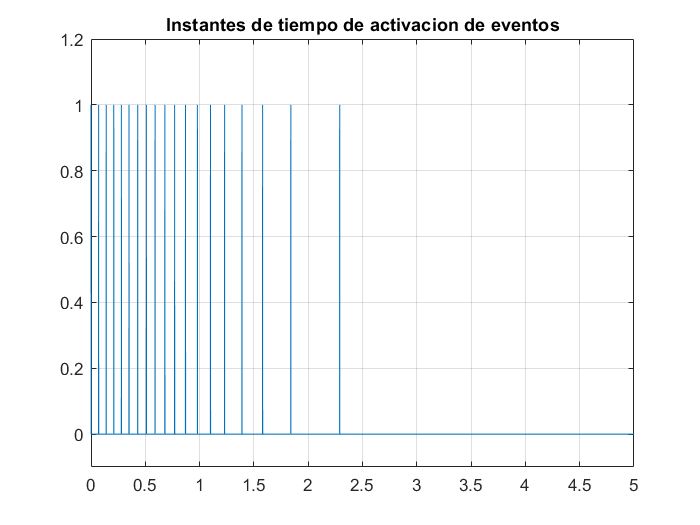

plot(t,[eventos 0]) %Instanes de activacion de eventos
axis([0 t(end) -0.1 1.2])
grid on
title('Instantes de tiempo de activacion de eventos')

cnt=eventos(1);
for i=2:length(eventos)
    if(eventos(i)==1)
        cnt(i)=cnt(i-1)+1;
    else
        cnt(i)=cnt(i-1);
    end
end

El numero total de eventos es:

Nro_eventos=length(find(eventos==1))

Nro_eventos = 19

Nro_activaciones=length(t)

Nro_activaciones = 5001

Grafica de eventos acumulativos de eventos a lo largo del tiempo

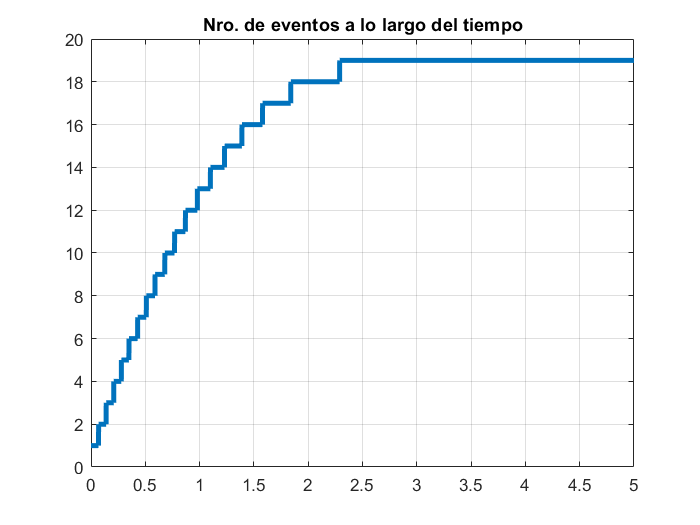

plot(t(1:end-1),cnt,'LineWidth',3)
grid on
title('Nro. de eventos a lo largo del tiempo')